# Neural Networks Part 1

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology. 

Neural networks work by taking linear combinations of predictors to construct new representations of our features. Non-linear functions are applied to the new features to model the potential non-linearity in the dataset. This can map the transformed values into either class labels for classification problems, or as probabilities.

In the next two lectures, we'll work on building the three main components of a neural network. Then, we will apply the neural network we wrote on a breast cancer dataset to predict whether a patient has a benign or malignant tumor. Finally, we will benchmark our model against other models and discuss the challenges of training a neural network and strategies to optimize the algorithm's performance.

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They can detect nonlinear relationships and interactions between predictor variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

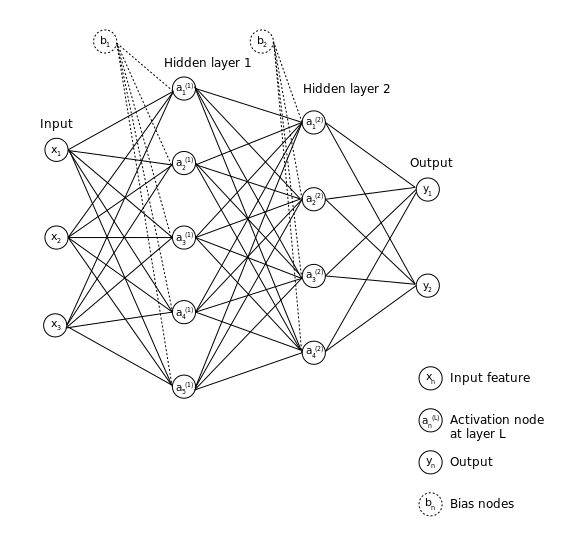

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network. 

**Each component of the feed-forward neural network is described below:**

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). In our data array, each $n^{\textrm{th}}$ column while each edge corresponds to a **weight** parameter. Further, we can choose to add more flexibility into the model by introducing some **bias** values. The diagram above shows 3 features in the input layer, 15 different weights to train, and a bias parameter.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and they represent a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs on complex data is known as **deep learning**. 

The diagram above shows a deep neural network with two hidden layers, nine activation nodes, 20 weight parameters, and a single bias parameter.

**The output layer**

From the last hidden layer, the values are transformed once more to the **output layer**. Here, we can use rules to turn these values into labels for a classification problem, or keep the raw values / probabilities in a regression problem. The diagram above shows two output nodes corresponding to two classes and 6 weight vectors to learn.

To illustrate the main concepts underpinning neural networks for the next two lectures, we'll code up a shallow feedforward neural network from scratch. There are three main phases in a feedforward neural network that we'll go over for the remaining lecture: 

- Training the model in forward propagation

- Evaluating the performance of the training phase using a cost function

- Tuning / correcting model parameters using backward propagation

## Step 1: Training a neural network using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the predictor variables from the input dataset, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset `X` with 20 observations and 3 preditor variables. We are also assuming that there are 3 activation nodes in the hidden layer with a single weight connecting each input node to an activation node. The formula to take a linear combination of predictors is shown below. The new features are stored in the variable `Z`.


$$Z=X^T w+b$$


#### Analogy to linear regression

While this problem is slightly different from a linear regression problem in that we are solving for the output `Z` rather than using `X` and `Z` to estimate our coefficients, we actually have the same objective! In a neural network, we're trying to estimate two parameters: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

However, in contrast to a linear regression problem, we perform the "learning' part of the neural network in a later phase. This allows us to capture more of the underlying complexity in the dataset.

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ impact the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

The plot is generated by a custom accessory function `plotLSLines` located in the lesson directory. 

% !!! IMPORTANT: ADD ALL FUNCTIONS TO MATLAB PATH !!!
addpath(genpath('.'))

% Initialize inputs using random numbers using a fixed random number generator (rng)
% for reproducibility
rng(2);
X = normrnd(0, 1, [3, 20]);

% Example with three different weight vectors
wArray = [[1; 0;  0], ...   % One weight
          [1; 5;  0], ...   % Two weights
          [1; 2; -5]];      % Three weights
b = randn([1, 20]) * 0.01;

% Construct several values for Z by changing the weight
% parameters and plotting the least-square lines.
for i = 1:size(wArray, 2)
    Z1{i} = X' * wArray(:, i) + b';
end
plotLSLines(X', Z1, 'weights')

As you can see, different combinations of weights influence `Z`, and show that this is a really important parameter to tune in the model.

#### Impact of biases on the new feature `Z` generated by the neural network 

Now that we saw how the weights scale our features linearly, let's see how the biases influence the output `Z`. 

w = [1; 2; -5];                     % Three activation nodes with fixed values
bArray = [zeros([1, 20]); ...        % All zeros
          randn([1, 20]) * 0.01; ... % Small random values
          ones( [1, 20])];           % All tens

for i = 1:size(wArray, 2)
    Z2{i} = X' * w + bArray(i, :)';
end
plotLSLines(X', Z2, 'biases')

The bias parameter at first glance seems to have very little impact on the model's output. However, it has an apparent impact when we apply a non-linear transformation to the dataset.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. 

We'll discuss why we need to initialize neural networks with small and random values for these parameters in the next lecture.  

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the pros / cons of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function and the ideal distribution is shown below:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


plotSigmoidFunction()

The plot is generated by a custom accessory function `plotSigmoidFunction` located in the lesson directory. 

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`w`

% Compute y using the Z1 cell array containing the results from using different w values
for i = 1:size(Z1, 2)
    y1{i, :} = activationFnc(Z1{i}', 'Sigmoid');
end
plotSigmoidFunction(X', y1, 'weights')

As we add additional weight parameters, the transformed values tend to converge to a value of 0 and 1. This feature of the sigmoid activation function is especially useful for binary classification, where we need to draw out a decision boundary between two classes.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`b`

% Compute y using the Z2 cell array containing the results from using different b values
for i = 1:size(Z2, 2)
    y2{i} = activationFnc(Z2{i}', 'Sigmoid');
end
plotSigmoidFunction(X', y2, 'biases')

Using a bias value of either 0 or small random initializations results in faster convergence of transformed datapoints to either 0 or 1, compared to setting b = 1. However, setting b=0 and b=random does produce slightly different results. It turns out that after several iterations of forward propagation, the bias will help these values converge faster than setting b=0.

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\mathrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \mathrm{if}\;z\ge 0\\
0 & \mathrm{if}\;z<0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution:

plotReLU()

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution:

plotLeakyReLU()

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A full round of forward propagation

Let's now put all of these concepts together to run forward propagation in a shallow neural network using a breast cancer datasets built into MATLAB. 

The dataset can be called using the `load cancer_dataset `function, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

To save space in the code blocks in this lecture, an accessory function `loadCancerData` has been made to:

- Load the dataset and target variables

- Split the dataset and target variables into training and test datasets

- Standardize the input datasets to have a mean = 0 and standard deviation of 1. 

We'll use only 2 activation nodes in the hidden layer.** Our hypothesis is that two activation nodes are able to capture the differences in a 2-class (binary) classification problem. **We'll discuss a systematic way to choose the number of hidden nodes needed to optimize the performance of the neural network in the next lecture.

The ReLU activation function will be used to demonstrate the implementation of forward propagation. However, you can feel free to test out the other activation functions, and how they impact the output from the model. 

clear all;
rng(2);

% Load the cancer data
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

numberOfHiddenNodes = 2;
actFnc = 'ReLU';

% Intialize the weights and biases from input -> hidden layer
w1 = randn([size(Xtrain, numberOfHiddenNodes), 2]) * 0.01;
b1 = randn([size(Xtrain, 1), 1]) * 0.01;

Let's now run forward propagation, first from the input layer to the hidden layer:

Z1 = Xtrain * w1 + b1;
A1 = activationFnc(Z1, actFnc);

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round. Additionally, we will not add additional biases in this layer. Finally, we'll use the same activation function.

% Intialize the weights from input -> hidden layer
w2 = rand(size(A1, 2), 1) * 0.01;
b2 = 0;

Z2 = A1 * w2 + b2;
A2 = activationFnc(Z2, actFnc);
ypred = A2;

That's one full round of forward propagation! Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **Cross-Entropy cost function.**

### **Cross-Entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ = number of observations, $y_{\textrm{train}}$ = the response variable, and $y_{\textrm{pred}}$ = the predicted value for$y_{\textrm{train}}$ from forward propagation. The **cost** value can be computed using the `costFunction` function provided. The docstring is provided below:

J = costFunction(Ytrain, ypred, 'Log-Loss')

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Step 3: Optimizing neural network parameters using backward propagation

After computing the cost, we need to optimize the model parameters (`w` and `b)` until the error is either below a given threshold we assign, or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called **gradient descent, **where we're adjusting the model parameters by following the gradient that minimizes the model error. Specifically for neural networks, we need to **back propagate** and compute the gradients **dW** and **db** using the variables we computed in forward propagation. 

### Finding the gradients dW and db using back propagation

To propagate the loss $J$ with respect to the parameters $W$ and $b$, we need to compute the gradients `dW` and `db. `Two differential equations are used:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

We won't go over the derivation for each term, but in practice, we would work these differential equations individually, multiply them together as shown above, and carry out gradient descent for each layer and each parameter in the neural network. After working out the differential equations, we get the following set of equations that are needed to compute `dw2`, `dw1`, and `db1.`

Output layer to hidden layer: $\textrm{dZ2}=\textrm{A2}-Y_{\textrm{train}} ;\;d\textrm{W2}=\textrm{dZ2}\cdot {\textrm{A1}}^T \cdot \frac{1}{m}$; $\;\textrm{db2}=0$

Hidden layer to input layer: $\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right);\;d\textrm{W1}=\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \cdot \frac{1}{m};\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$

The sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\;\textrm{sigmoid}\left(\textrm{Z1}\right)\cdot \left(1-\textrm{sigmoid}\left(\textrm{Z1}\right)\right)\equiv \left(1-{\textrm{A2}}^2 \right)$

### A full round of back propagation

Now let's codify the expressions above to run a full round of back propagation. First we need to initialize constants that will be used in back propgation. A good starting point for the learning rate is 0.05. 

alpha = 0.05;
m = size(Xtrain, 1);

First let's back propagate from the output layer to the hidden layer:

dZ2 = A2 - Ytrain;
dW2 = (1/m) .* (A1' * dZ2);

Next let's back propagate from the hidden layer to the input layer:

dZ1  = (w2 * dZ2') .* (1 - A1.^2)';
dW1  = (1/m) .* Xtrain' * dZ1';
db1  = (1/m) .* sum(dZ1', 2);

### Optimizing parameters `W` and `b` using gradient descent

Recall that the objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \textrm{db}\right)
\end{array}$$
 

where $\alpha$ is the learning rate hyperparameter, a constant value that controls how fast we move along the gradient.  

We can perform gradient descent using the code below.

w2 = w2 - (alpha .* dW2);
w1 = w1 - (alpha .* dW1);
b1 = b1 - (alpha .* db1);

We have successfully back propagated to get better values for `W` and `b.` To train the neural network even more, we would iterate the entire process of forward propagation, computing the cost, and backward propagation several times until we reach the minimum cost value. We'll do this in the next lecture.

## Summary

We have covered how neural networks work under the hood, and coded a shallow neural network from scratch. In the next lecture, we'll combine what we've learned in this lecture and train a shallow neural network using a breast cancer dataset. We will also cover some of the issues commonly encountered in training a neural network. Finally, we'll benchmark the neural network against a logistic regression classifier.

## Additional reading and references 

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).